% Clear (!!!Save your workspace first!!!)
clc;
clear;
close all;
load('dataset.mat')

% data set from tracker
t = J1dataset.t;
% Position
x0 = J0dataset.x;   % Joint 0 (Foot)
y0 = J0dataset.y;
x1 = J1dataset.x;   % Joint 1 (Ankel)
y1 = J1dataset.y;
x2 = J2dataset.x;   % Joint 2 (Knee)
y2 = J2dataset.y;
x3 = J3dataset.x;   % Joint 3 (Thigh)
y3 = J3dataset.y;

l0 = mean(((x1 - x0).^2 + (y1 - y0).^2).^0.5);   % Distance from J1 to J0
l1 = mean(((x1 - x2).^2 + (y1 - y2).^2).^0.5);   % Distance from J1 to J2
l2 = mean(((x3 - x2).^2 + (y3 - y2).^2).^0.5);   % Distance from J2 to J3

% Discretize Dataset
tspan = linspace(t(1),t(end),1200)';

% Position
x0ref = interp1(t,x0,tspan);
y0ref = interp1(t,y0,tspan);
x1ref = interp1(t,x1,tspan);
y1ref = interp1(t,y1,tspan);
x2ref = interp1(t,x2,tspan);
y2ref = interp1(t,y2,tspan);
x3ref = interp1(t,x3,tspan);
y3ref = interp1(t,y3,tspan);

%parameters
params = [];
params.l0 = l0; % [m]
params.l1 = l1; % [m]   
params.l2 = l2; % [m]
params.mb = 73; % [kg]
params.totalleg_m = 17.555; % [kg] (1 side / men)
params.totalupper_m = params.mb - 2*params.totalleg_m; % [kg] upper body
params.g = 9.81; % [m/s^2]
params.upperload = params.g * params.totalupper_m;
params.upperleg = 0.105 * params.mb/2;      %[kg] (1 side / men)
params.lowerleg = 0.0475 * params.mb/2;     %[kg] (1 side / men)
params.foot = 0.0143 * params.mb/2;         %[kg] (1 side / men)

%% Setup Kinematics
Ts = 0.1/3;
tmax = t(end);

%Inverse kinematics
theta0 = atan2(y1ref-y0ref,x1ref-x0ref);
theta1 = atan2(y2ref-y1ref,x2ref-x1ref)- theta0;
theta2 = atan2(y3ref-y2ref,x3ref-x2ref)- theta0 - theta1;

%% Simmechanic
x0inp = [tspan x0ref];
y0inp = [tspan y0ref];

theta0inp = [tspan theta0];
theta1inp = [tspan theta1];
theta2inp = [tspan theta2];
out = sim('SimModel.slx');

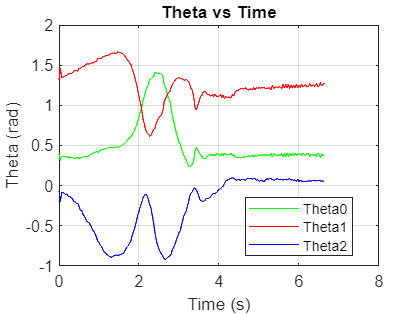

% Plot theta vs time
plot(tspan,theta0,'g')
hold on
plot(tspan,theta1,'r')
plot(tspan,theta2,'b')
hold off
title("Theta vs Time")
xlabel("Time (s)")
ylabel("Theta (rad)")
legend("Theta0","Theta1","Theta2","Location","best")
grid on

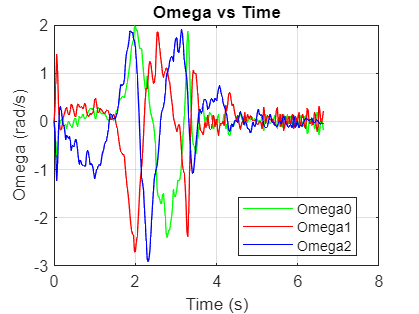


% Plot omega vs time
tspannew = linspace(t(1),t(end),299);
plot(tspannew,out.omega0(:),'g')
hold on
plot(tspannew,out.omega1(:),'r')
plot(tspannew,out.omega2(:),'b')
hold off
title("Omega vs Time")
xlabel("Time (s)")
ylabel("Omega (rad/s)")
legend("Omega0","Omega1","Omega2","Location","best")
grid on

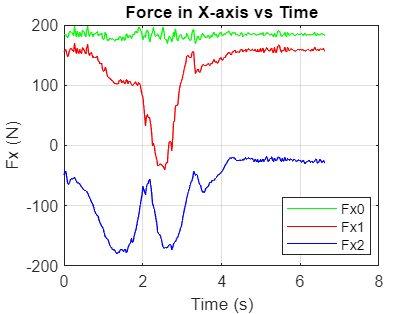


% Plot Force in X-axis
plot(tspannew,out.J0force(1,:)','g')
hold on
plot(tspannew,out.J1force(1,:)','r')
plot(tspannew,out.J2force(1,:)','b')
hold off
title("Force in X-axis vs Time")
xlabel("Time (s)")
ylabel("Fx (N)")
legend("Fx0","Fx1","Fx2","Location","best")
grid on

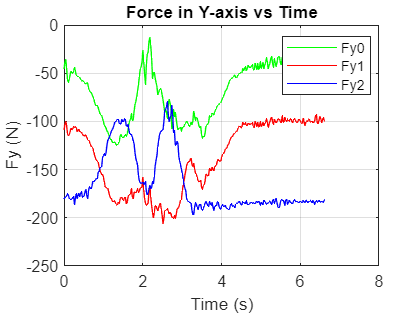


% Plot Force in Y-axis
plot(tspannew,out.J0force(2,:)','g')
hold on
plot(tspannew,out.J1force(2,:)','r')
plot(tspannew,out.J2force(2,:)','b')
hold off
title("Force in Y-axis vs Time")
xlabel("Time (s)")
ylabel("Fy (N)")
legend("Fy0","Fy1","Fy2","Location","best")
grid on

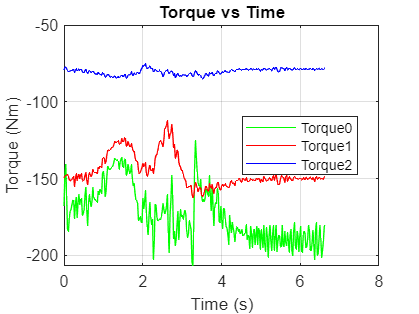


% Plot Torque
plot(tspannew,out.J0torque(3,:)','g')
hold on
plot(tspannew,out.J1torque(3,:)','r')
plot(tspannew,out.J2torque(3,:)','b')
hold off
title("Torque vs Time")
xlabel("Time (s)")
ylabel("Torque (Nm)")
legend("Torque0","Torque1","Torque2","Location","best")
grid on

% Energy
energy = params.mb*params.g*(y0ref(end) - y0ref(1))

energy = 164.0868